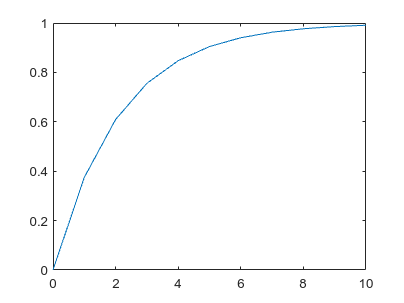

clear all
x = zeros(1, 6);
x(1) = 0;
h = 0.1;
T = 1;
t = zeros(1, 6);
r = 1;
for i = 1: T/h
    t(i + 1) = t(i) + 1;
    f1 = 5 * r - 5 * x(i);
    x0 = x(i) + h * f1; % eular predict
    f2 = 5 * r - 5 * x0;
    x(i + 1) = x(i) + h/2 * (f1 + f2);% 
end
plot(t, x)